# Calibration results in terms of RMSE

## Grouped bar graph comparing calibration algorithms

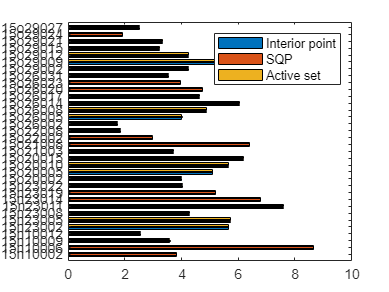

clc
clearvars
close all

exp_num1 = "exp35";
exp_num2 = "exp36";
exp_num3 = "exp37";
group = "wt";

rmse_df1 = readtable(fullfile(pwd,"log",strcat(exp_num1,"_",group,".csv")));
rmse_df2 = readtable(fullfile(pwd,"log",strcat(exp_num2,"_",group,".csv")));
rmse_df3 = readtable(fullfile(pwd,"log",strcat(exp_num3,"_",group,".csv")));
rmse_df_comb = join(rmse_df1,rmse_df2, 'Keys','File');
rmse_df_comb = join(rmse_df_comb,rmse_df3, 'Keys','File');

file_names = categorical(rmse_df_comb.File);
rmse = table2array(rmse_df_comb(:,2:end));

figure('Color','w')
barh(file_names,rmse)
legend(["Interior point","SQP","Active set"])

% set(gca, 'FontName','Arial', 'FontSize',11, 'FontWeight','bold')

## Bar graph comparing RMSEs across datasets

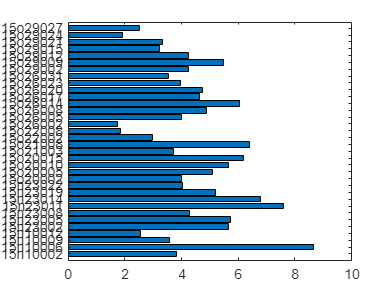

file_group = "wt";
exp_num = "exp35";

rmse_df = readtable(fullfile(pwd,"log",strcat(exp_num,"_",file_group,".csv")));
file_names = categorical(rmse_df.File);
rmse = rmse_df.RMSE;

figure('Color','w')
barh(file_names,rmse)

% set(gca, 'FontName','Arial', 'FontSize',11, 'FontWeight','bold')

# Directly comparing model prediction and experimental data

## The 25-sec-pulse data

clc
close all
clearvars

group = "ko";
exp_num = "exp41";
file_name = "15o27006.xlsx";

data_path = fullfile(pwd,"data",strcat(group,"-preprocessed-25s"),file_name);
calib_path = fullfile(pwd,strcat("calib_",exp_num,"_",group),file_name);

current_names = {'iktof', 'ikslow1', 'ikslow2', 'ikss'};
tune_idx1{1} = [1, 2, 4, 5, 7, 11, 13];
tune_idx1{2} = [1, 2, 4, 5, 9, 10, 11];
tune_idx1{3} = [2, 3];
tune_idx1{4} = [1, 2, 3, 4];

% import the experimental data and calibration results
exp_mx = table2array(readtable(data_path));
sol_mx = table2array(readtable(calib_path));
t = exp_mx(:,1);
yksum = exp_mx(:,2);

% protocol
ideal_hold_time = 470;
ideal_end_time = 25*1000;
hold_volt = -70;
volt = 50;
ek = -91.1;

% estimate the critical time points
[~, ideal_hold_idx] = min(abs(t - ideal_hold_time));
[~, ideal_end_idx] = min(abs(t - ideal_end_time));
t = t(1:ideal_end_idx);
yksum = yksum(1:ideal_end_idx);

% time space
time_space = cell(1,3);
time_space{1} = t;
time_space{2} = t(1:ideal_hold_idx);
pulse_t = t(ideal_hold_idx+1:end);
pulse_t_adj = pulse_t - pulse_t(1);
time_space{3} = pulse_t_adj;

% protocol
protocol = cell(1,4);
protocol{1} = hold_volt;
protocol{2} = ek;
protocol{3} = volt;
protocol{4} = time_space;

% prediction from the calibration resukt
[model_info, psize] = gen_mdl_struct(current_names, tune_idx1);
sol = gen_sol_vec(sol_mx, model_info, psize);
[z,yksum_hat,comp_hat] = rmsey(sol, yksum, model_info, protocol);

% figure 1: yksum
figure('Color','w', 'Position',[100,100,560,420])
plot(t,yksum, 'Color','black')
hold on
plot(t, yksum_hat{1}, '--', 'Color','red');
hold off
set(gca, 'XLimSpec','tight')
legend("Experimental Data","Model Prediction")

% figure 2: individual K+ currents
comp_hat = comp_hat{1};
figure('Color','w', 'Position',[600,100,560,420])
plot(t,comp_hat{1})
hold on
plot(t,comp_hat{2})
plot(t,comp_hat{3})
plot(t,comp_hat{4})
hold off
set(gca, 'XLimSpec','tight')
legend("I_{Kto,f}","I_{Kslow1}","I_{Kslow2}","I_{Kss}")

## The 4.5-sec-pulse data

clc
close all 
clearvars

file_group = "ko";
exp_num = "exp45";
file_name = '15o27002.xlsx';
save_dir = strcat('calib_', exp_num);

% import calibration results
calib = table2array(readtable(fullfile(pwd, strcat(save_dir, '_', file_group), file_name)));

%----- Model structure -----%
current_names = {'iktof', 'ikslow1', 'ikslow2', 'ikss'};

tune_idx = cell(5,1); % iktof, iktos, ikslow1, ikslow2, ikss
tune_idx{1} = [1, 2, 4, 5, 7, 11, 13];
tune_idx{2} = [2, 3];
tune_idx{3} = [1, 2, 4, 5, 9, 10, 11];
tune_idx{4} = [2, 3];
tune_idx{5} = [1, 2, 3, 4];

[mdl_struct, psize] = gen_mdl_struct(current_names, tune_idx);
sol = gen_sol_vec(calib, mdl_struct, psize);

pdefault = cell(5,1);
pdefault{1} = [33, 15.5, 20, 7, 0.03577, 0.06237, 0.18064, 0.3956, ...
    0.000152, 0.067083, 0.00095, 0.051335, 0.3846];
pdefault{2} = [-1050, 270, 0.0629];
pdefault{3} = [22.5, 45.2, 40.0, 7.7, 5.7, 0.0629, 6.1, 18, 2.058, 803.0, 0.16];
pdefault{4} = [4912, 5334, 0.16];
pdefault{5} = [0.0862, 1235.5, 13.17, 0.0611];

%----- Protocol & Experimental data -----%
exp_data = table2array(readtable(fullfile(pwd,'mgat1ko_data', ...
    strcat(file_group, '-preprocessed'), file_name)));
t = exp_data(:,1);
yksum = exp_data(:,2:end);

hold_volt = -70;
volts = -30:10:50;
ideal_hold_time = 120;
ideal_end_time = 4.6*1000;
ek = -91.1;

[~, ideal_hold_idx] = min(abs(t - ideal_hold_time));
[~, ideal_end_idx] = min(abs(t - ideal_end_time));
t = t(1:ideal_end_idx);
yksum = yksum(1:ideal_end_idx, :);

protocol = cell(6,1);
protocol{1} = hold_volt;
protocol{2} = ek;
protocol{3} = volts;
protocol{4} = t;
protocol{5} = t(1:ideal_hold_idx);
pulse_t = t(ideal_hold_idx+1:end);
pulse_t_adj = pulse_t - pulse_t(1);
protocol{6} = pulse_t_adj;

%----- Generate yksum_hat -----%
r = obj_rmse(sol, @kcurrent_basic, mdl_struct, pdefault, protocol, yksum);
fprintf('File %s Min RMSE: %f \n', file_name, r)

File 15o27002.xlsx Min RMSE: 1.149898 


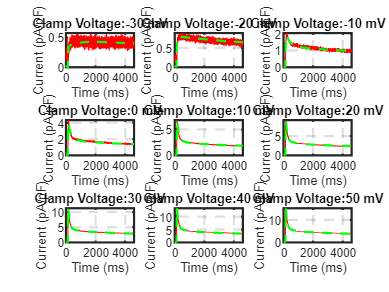


figure('Color','w')
for i=1:length(volts)
    yksum_i = yksum(:, i);
    ymx = kcurrent_basic(sol, mdl_struct, pdefault, protocol, volts(i));
    yksum_hat1 = sum(ymx,2);

    subplot(3, 3, i)
    plot(t, yksum_i, 'Color','red')
    hold on
    plot(t, yksum_hat1, '--', 'Color','green', 'LineWidth',1.5)
    hold off
    axis tight
    grid on
    title(strcat('Clamp Voltage: ', string(volts(i)), ' mV'));
    xlabel('Time (ms)');
    ylabel('Current (pA/pF)');
    get(gcf,'CurrentAxes');
    set(gca,'YDir','normal');
    set(gca,'LineWidth',1.5);
    set(gca,'GridLineStyle','--')
end

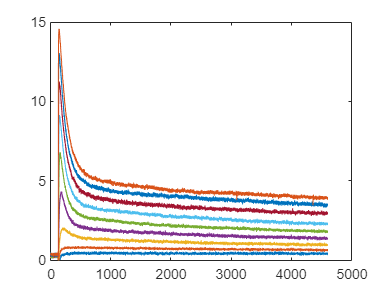


figure('Color','w')
plot(t, yksum(:, 1))
hold on
for i = 2:length(volts)
    plot(t, yksum(:, i))
end
hold off

# Custom functions

function [mdl_struct, psize] = gen_mdl_struct(current_names, tune_idx)
    num_currents = length(current_names);
    
    % index 1
    idx_info1 = cell(1,num_currents);
    for i = 1:num_currents
        switch current_names{i}
            case 'iktof'
                idx_info1{i} = tune_idx{1};
            case 'iktos'
                idx_info1{i} = tune_idx{2};
            case 'ikslow1'
                idx_info1{i} = tune_idx{3};
            case 'ikslow2'
                idx_info1{i} = tune_idx{4};
            case 'ikss'
                idx_info1{i} = tune_idx{5};
        end
    end

    % index 2
    idx_info2 = cell(1,num_currents);
    psize = 0;
    for i = 1: num_currents
        psize_old = psize;
        psize = psize + length(idx_info1{i});
        idx_info2{i} = (1+psize_old):(psize);
    end

    model_info = [current_names; idx_info1; idx_info2];
    field_names = ["name","idx1","idx2"];
    mdl_struct = cell2struct(model_info, field_names, 1);    
end

function sol = gen_sol_vec(sol_mx, model_struct, psize)
    sol = zeros(1, psize);
    for i = 1:length(model_struct)
        running_sol = sol_mx(:, i);
        running_sol = running_sol(~isnan(running_sol));
        sol(model_struct(i).idx2) = running_sol(model_struct(i).idx1);
    end
end